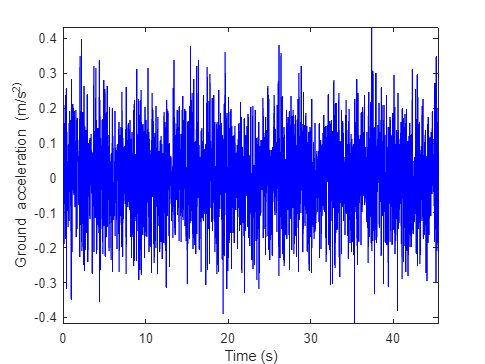

% Existing code for ground acceleration generation
clearvars; close all; clc;

f = linspace(0,45,2048); % frequency vector
zeta = 0.5; % bandwidth of the earthquake excitation.
sigma = 0.5; % standard deviation of the excitation.
fn = 20; % dominant frequency of the earthquake excitation (Hz).
T90 = 1; % value of the envelop function at 90 percent of the duration.
eps = 0.9; % normalized duration time when ground motion achieves peak.
tn = 50; % duration of ground motion (seconds).

% Function call to generate ground acceleration
[y, t] = seismSim(sigma, fn, zeta, f, T90, eps, tn); 
% y: acceleration record
% t: time

% Plot the generated ground acceleration
figure;
plot(t, y, 'b');
xlabel('Time (s)');
ylabel('Ground acceleration (m/s^2)');
axis tight;

set(gcf, 'color', 'w');

% Step 1: Normalize the signal for audio playback
y_normalized = (y - min(y)) / (max(y) - min(y));  % Normalize to 0-1
y_audio = y_normalized * 2 - 1; % Scale to range [-1, 1] for audio playback

% Step 2: Resample the signal to increase playback duration
desired_duration = 3; % Set the desired playback duration in seconds
fs = 44100; % Standard audio sampling rate (44.1 kHz)
original_duration = length(t) / (length(t) / tn); % Original duration of the signal
resample_factor = desired_duration / original_duration; % Resampling factor

% Resample the signal
y_resampled = resample(y_audio, round(fs * desired_duration), length(y_audio)); 

% Step 3: Play the waveform using MATLAB's sound function
disp('Playing the waveform on system audio...');

Playing the waveform on system audio...


sound(y_resampled, fs); % Play the audio waveform
pause(desired_duration); % Pause to allow playback to complete
disp('Playback complete.');

Playback complete.



% Optional: Save the audio as a .wav file
audiowrite('ground_acceleration_long.wav', y_resampled, fs);

disp('Audio waveform saved as "ground_acceleration_long.wav".');

Audio waveform saved as "ground_acceleration_long.wav".
